## BIV-Übung 2

Hadi Saleh 1822230

### 2 Histogramme bei Farbbildern: Scatterplots

a)

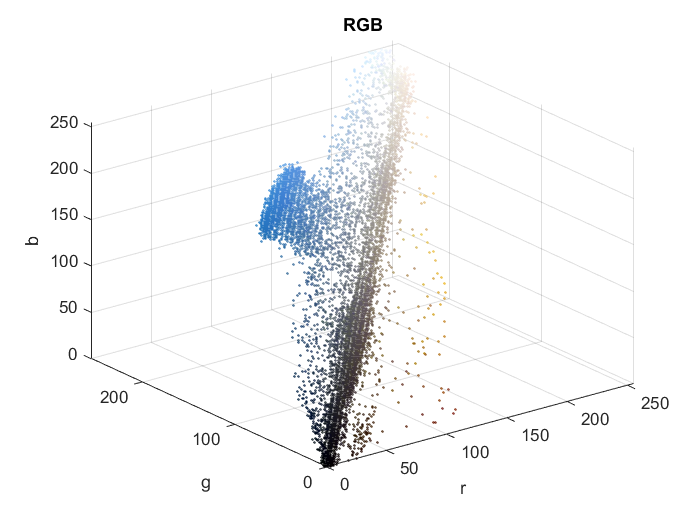

moewe=imread('moewex.jpg');
list_rgb = reshape(moewe, [], 3);
figure
scatter3(list_rgb(:, 1), list_rgb(:, 2), list_rgb(:, 3), 1, double(list_rgb) / 255)
xlabel('r')
ylabel('g');
zlabel('b');
title('RGB');
xlim([0 255])
ylim([0 255])
zlim([0 255])

b) Zum Himmel gehört den blauen Teil, alles anderes (schwarz-braun-weißer Teil) zur Möwe. Himmel nimmt weniger Platz weil alle seine Pixel fast die gleiche Farbe haben (sehr wenig Kontrast), aber bei der Möwe gibt es mehreren Farben mit höher Kontrast (Anzahl von Pixel mit der Farbe hat weniger Einfluss auf den Scatterplot, viel wichtiger sind viele benachbarten Farben, auch wenn von jeder Farbe nur ein Pixel im Bild gibt)

c)

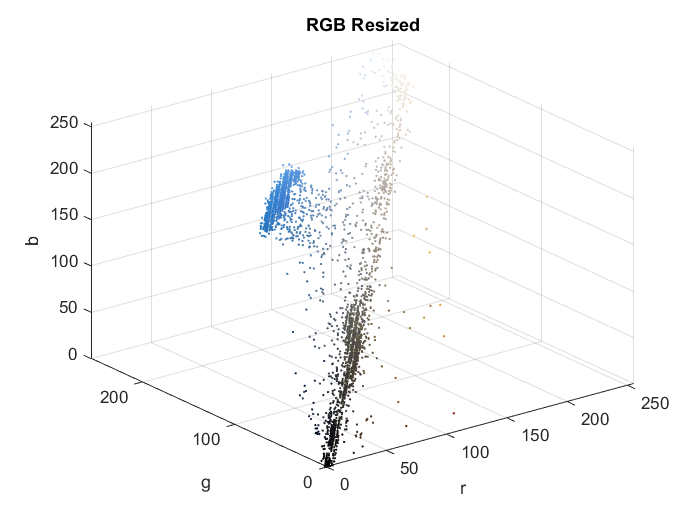

moeweResized=imresize(moewe,0.4,'nearest');
list_rgb_resized = reshape(moeweResized, [], 3);
figure
scatter3(list_rgb_resized(:, 1), list_rgb_resized(:, 2), list_rgb_resized(:, 3), 1, double(list_rgb_resized) / 255)
xlabel('r')
ylabel('g');
zlabel('b');
title('RGB Resized');
xlim([0 255])
ylim([0 255])
zlim([0 255])

Blau ist immer noch klein aber es ist dicker (die Pixel sind näher zueinander) als bei der Möwe, dessen Farben dünner sind (weniger Pixel pro Einheit) aber nehmen mehr Platz weil sie diverser sind.

d) der blaue Block enthält die meiste Pixel im Bild. seine r, g und b Koordinate (ungefähr) sind die gleiche wie die "Peaks" in den Histogrammen, nämlich r=81, g=150 und b=219, 

e) 

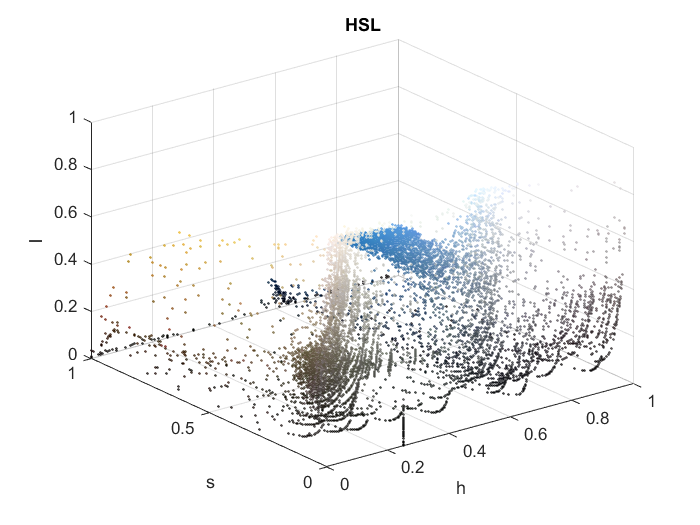

moeweHsi = rgb2hsi(moewe);
list_hsi = reshape(moeweHsi, [], 3);
figure
scatter3(list_hsi(:, 1), list_hsi(:, 2), list_hsi(:, 3), 1, double(list_rgb) / 255)
xlabel('h');
ylabel('s');
zlabel('l');
title('HSL');

f)

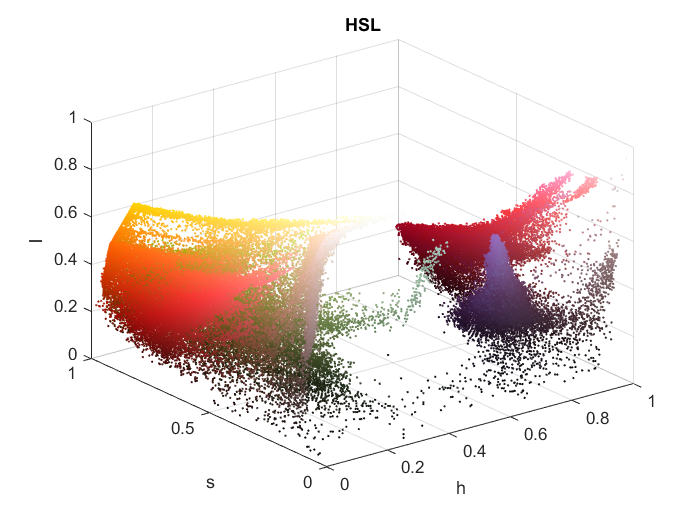

pepper_rgb = imread('peppers.png');
pepper_hsi = rgb2hsi(pepper_rgb);
list_rgb_pepper = reshape(pepper_rgb, [], 3);
list_hsi_pepper = reshape(pepper_hsi, [], 3);
figure
scatter3(list_hsi_pepper(:, 1), list_hsi_pepper(:, 2), list_hsi_pepper(:, 3), 1, double(list_rgb_pepper) / 255)
xlabel('h');
ylabel('s');
zlabel('l');
title('HSL');